% Parse Simulation Output Structure
t = out.simOut.time;
q = out.simOut.signals.values(:,1:4);               % quaternion attitude
w = (out.simOut.signals.values(:,5:7));      % rates (deg/sec)
trq = out.simOut.signals.values(:,8:10);            % reaction wheel torques (N-m)
qe = out.simOut.signals.values(:,11:14);            % quaternion error
err = fliplr(rad2deg(quat2eul(qe)));                        % error (euler angle) (deg)
% att = out.simOut.signals.values(:,15:17);
att = rad2deg(quat2eul(q));
% att = mod(att,180);
% att(:,1) = mod(att(:,1),180);
% att(:,2) = mod(att(:,2),90);
% att(:,3) = mod(att(:,3),180);
pos_rw = rad2deg(out.simOut.signals.values(:,[end-5,end-3,end-1]))/6; % reaction wheel angle (deg)
vel_rw = rad2deg(out.simOut.signals.values(:,[end-4,end-2,end]))/6;   % reaction wheel velocity (deg/sec)

## Plot Full Mission

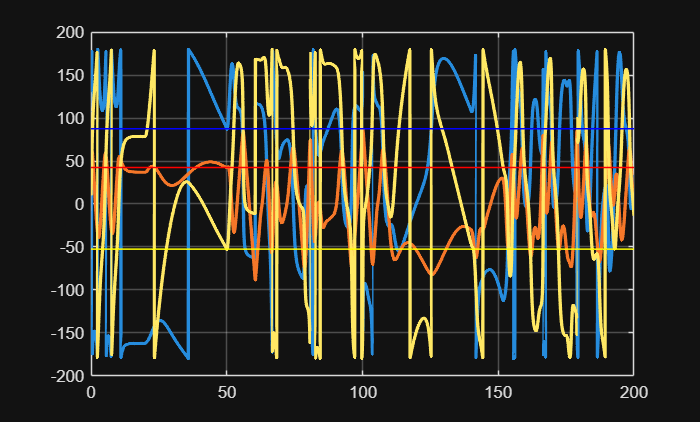

figure;
set(gca,'Visible','on')
tiledlayout('vertical')
nexttile
plot(t,att,LineWidth=2)
% hold on
% plot([0 200],[87.5335 87.5335],'b')
% plot([0 200],[42.4422  42.4422],'r')
% plot([0 200],[-52.5079 -52.5079],'y')
grid on

legend('Roll','Pitch','Yaw')
title('Full Mission')
xlabel('Time (s)')
ylabel('Error (deg)')
ylim([-200 200])
nexttile
plot(t,w,LineWidth=2)
grid on
legend('\omega_x','\omega_y','\omega_z')
xlabel('Time (s)')
ylabel('Rates (deg/s)')
ylim([-60 60])

## Plot Alignment to Initial Target Estimate

% figure;
% 
% t0 = simIn.ctrlTimes(1); tf = simIn.ctrlTimes(3);
% t0_idx = find(t>=t0,1,'first');
% tf_idx = find(t>=tf,1,'first');
% 
% tiledlayout('vertical')
% nexttile
% plot(t(t0_idx:tf_idx),att(t0_idx:tf_idx,:),LineWidth=2)
% grid on
% legend('Yaw','Pitch','Roll')
% title('Rate Damping')
% xlabel('Time (s)')
% ylabel('Error (deg)')
% ylim([-200 200])
% nexttile
% plot(t(t0_idx:tf_idx),w(t0_idx:tf_idx,:),LineWidth=2)
% grid on
% legend('\omega_x','\omega_y','\omega_z')
% xlabel('Time (s)')
% ylabel('Rates (deg/s)')
% ylim([-60 60])

## Plot Search for Target

% figure;
% 
% t0 = simIn.ctrlTimes(3); tf = simIn.ctrlTimes(4);
% t0_idx = find(t>=t0,1,'first');
% tf_idx = find(t>=tf,1,'first');
% 
% tiledlayout('vertical')
% nexttile
% plot(t(t0_idx:tf_idx),err(t0_idx:tf_idx,:),LineWidth=2)
% grid on
% legend('Yaw','Pitch','Roll')
% title('Search for Target')
% xlabel('Time (s)')
% ylabel('Error (deg)')
% ylim([-200 200])
% nexttile
% plot(t(t0_idx:tf_idx),w(t0_idx:tf_idx,:),LineWidth=2)
% grid on
% legend('\omega_x','\omega_y','\omega_z')
% xlabel('Time (s)')
% ylabel('Rates (deg/s)')
% ylim([-60 60])

## Plot Alignment to Target

% figure;
% 
% t0 = simIn.ctrlTimes(4); tf = simIn.ctrlTimes(4)+15;
% t0_idx = find(t>=t0,1,'first');
% tf_idx = find(t>=tf,1,'first');
% 
% tiledlayout('vertical')
% nexttile
% plot(t(t0_idx:tf_idx),err(t0_idx:tf_idx,:),LineWidth=2)
% grid on
% legend('Yaw','Pitch','Roll')
% title('Align to Target')
% xlabel('Time (s)')
% ylabel('Error (deg)')
% ylim([-200 200])
% xlim([50 65])
% nexttile
% plot(t(t0_idx:tf_idx),w(t0_idx:tf_idx,:),LineWidth=2)
% grid on
% legend('\omega_x','\omega_y','\omega_z')
% xlabel('Time (s)')
% ylabel('Rates (deg/s)')
% ylim([-110 110])
% xlim([50 65])

## Plot Reaction Wheel Velocity Profile

% figure
% plot(t,vel_rw(:,3),t,vel_rw(:,2),t,vel_rw(:,1))
% title('Reaction Wheel Velocity Profile')
% xlabel('Time (s)')
% ylabel('Velocity (deg/s)')
% legend('Yaw','Pitch','Roll')
% grid on

## Plot Reaction Wheel Dynamics

% r = 1;
% x = r*cosd(pos_rw(:,1));
% y = r*sind(pos_rw(:,1));
% 
% for i = 1:size(pos_rw,1)
%     quiver(0,0,x(i),y(i));
%     hold on
%     plot(r*cosd(0:pi/50:2*pi),r*sind(0:pi/50:2*pi));
%     xlim([-r r])
%     ylim([-r r])
%     title(['Time: ', num2str(round(t(k),2))]);  % display current time
%     drawnow
% end

## Video Generator

% vName = 'satellite_attitude_4.mp4';   % make sure this file doesn't already exist
% 
% v = VideoWriter(vName,'MPEG-4');
% v.FrameRate = 1/simIn.simTs;        % frames per second
% v.Quality   = 100;                  % 0–100 (mp4 only)
% open(v);                            % open video
% 
% % Cube centered at origin (3D Model)
% L = 1;          % side length
% V = L/2 * [
%    -1 -1 -1;
%     1 -1 -1;
%     1  1 -1;
%    -1  1 -1;
%    -1 -1  1;
%     1 -1  1;
%     1  1  1;
%    -1  1  1];   % vertices
% 
% F = [
%     1 2 3 4;
%     5 6 7 8;
%     1 2 6 5;
%     2 3 7 6;
%     3 4 8 7;
%     4 1 5 8];   % faces
% 
% 
% figure;
% set(gcf, 'Visible', 'on');
% % Create 3D model
% hSat = patch('Faces',F,'Vertices',V, ...
%              'FaceColor',[0.8 0.85 1], ...
%              'EdgeColor','k');
% 
% 
% % Plot parameters
% axis equal; grid on;
% xlabel('X'); ylabel('Y'); zlabel('Z');
% view(3);
% xlim([-2 2]); ylim([-2 2]); zlim([-2 2]);
% view(3)
% camlight
% lighting gouraud
% material dull
% camproj perspective
% scale = 2;  % scale for body axes
% hold on
% 
% % Plot initial body axes
% bX = quiver3(0,0,0, scale,0,0,'r','LineWidth',2);
% bY = quiver3(0,0,0, 0,scale,0,'g','LineWidth',2);
% bZ = quiver3(0,0,0, 0,0,scale,'b','LineWidth',2);
% 
% % Plot each frame for the duration of the mission
% for k = 1:2:length(t)
% 
%     qk = q(k,:);
%     att = quat2eul(qk);
%     R = eul2rotm([att(3), att(2), (att(1))]);   % [Yaw, Pitch, Roll]
% 
%     % Rotate satellite
%     Vrot = (R * V')';
%     set(hSat,'Vertices',Vrot);
% 
%     % Rotate body axes
%     set(bX,'UData',R(1,1)*scale,'VData',R(2,1)*scale,'WData',R(3,1)*scale);
%     set(bY,'UData',R(1,2)*scale,'VData',R(2,2)*scale,'WData',R(3,2)*scale);
%     set(bZ,'UData',R(1,3)*scale,'VData',R(2,3)*scale,'WData',R(3,3)*scale);
% 
%     title(['Time: ', num2str(round(t(k),2))]);  % display current time
% 
%     drawnow;
% 
%     legend('Satellite','X','Y','Z')
% 
%     % % Capture frame
%     % frame = getframe(gcf);
%     % writeVideo(v, frame);
% end
% 
% close(v);   % end video (call this command if you pause or stop before this line)